# Exercise 7

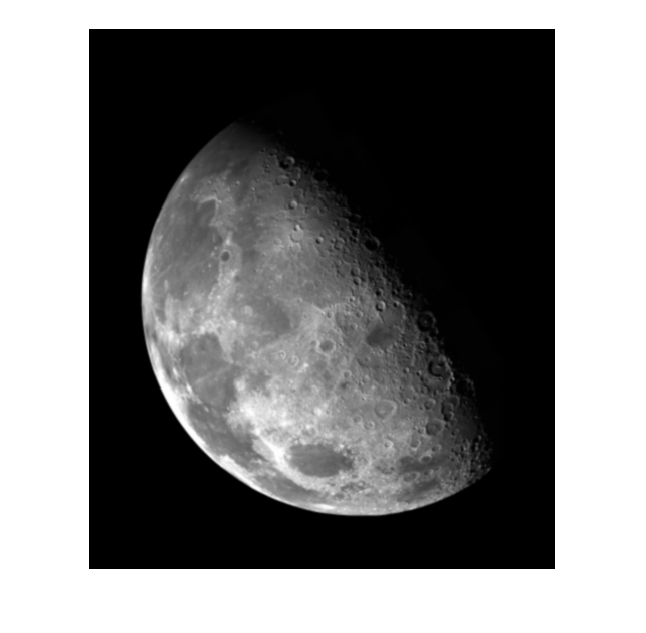

IM= imread('moon.tif');
imshow(IM);

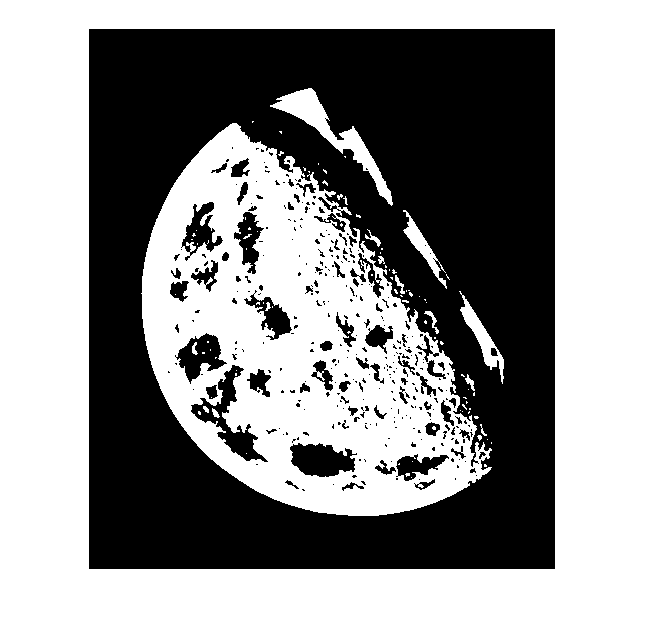


moonbin=imbinarize(IM,'adaptive','ForegroundPolarity','dark','Sensitivity',0.5);


% radius range
Rmin=5; 
Rmax=300

Rmax = 300


imshow(1-moonbin)
[centers, radii] = imfindcircles(1-moonbin,[Rmin Rmax],'ObjectPolarity','bright'); %%find ci

length(centers)

ans = 5

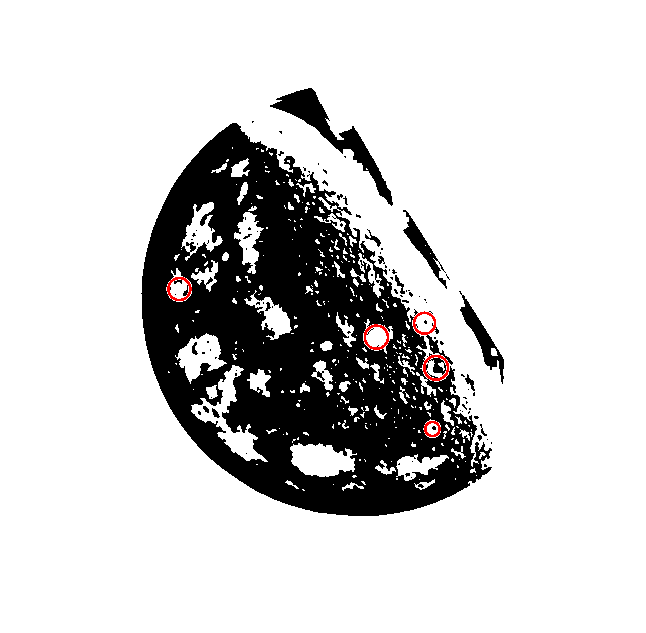


% viscircles will draw circles when centers and radii are given
hold on
viscircles(centers,radii);
hold off